# Neural-Network 3

Created time : 2024/5/24 09:49

學號 : 109321019    姓名 : 涂价弘

clear
clc

# CNN

## 步骤1：加载和显示图像数据

[XTrain,~,YTrain] = digitTrain4DArrayData;                       %加载训练图像样本

XTrain = XTrain(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         

YTrain =    -42
   -15
   -24
   -44
    13
    21
    19
   -35
   -40
    23


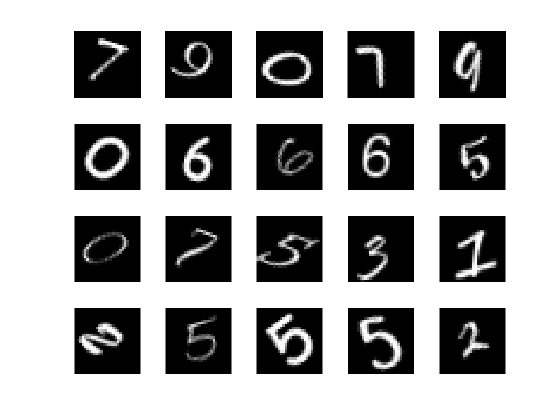

[XValidation,~,YValidation] = digitTest4DArrayData;              %加载验证图像样本

% 随机显示20幅训练图像
numTrainImages = numel(YTrain);                                  %统计用于训练样本的数量
figure
idx = randperm(numTrainImages,20);
for i = 1:numel(idx)
    subplot(4,5,i)
    imshow(XTrain(:,:,:,idx(i)))
    drawnow
end

## 步骤2:构建卷积神经网络

layers = [
    imageInputLayer([28 28 1])                                 % 输入层，1个通道，像素为28×28

    convolution2dLayer(3,8,'Padding','same')                   % 卷积层1：卷积核大小为3×3，卷积核的个数为8（每个卷积核的通道数与输入图像的通道数相等，本层中每个卷积核1个通道）卷积的方式采用零填充方式（即设定为same方式）
    batchNormalizationLayer                                    % 批量归一化层1
    reluLayer                                                  % ReLU非线性激活函数1
    averagePooling2dLayer(2,'Stride',2)                        % 池化层1：池化方式：平均池化；池化区域为2×2，步长为2

    convolution2dLayer(3,16,'Padding','same')                  % 卷积层2：卷积核大小为3×3，卷积核的个数为16（每个卷积核的通道数与输入特征图的通道数相等，本层中每个卷积核8个通道）卷积的方式采用零填充方式（即设定为same方式）
    batchNormalizationLayer                                    % 批量归一化层2
    reluLayer                                                  % ReLU非线性激活函数2
    averagePooling2dLayer(2,'Stride',2)                        % 池化层2：池化方式：平均池化；池化区域为2×2，步长为2

    convolution2dLayer(3,32,'Padding','same')                  % 卷积层3：卷积核大小为3×3，卷积核的个数为32（每个卷积核的通道数与输入特征图的通道数相等，本层中每个卷积核16个通道）卷积的方式采用零填充方式（即设定为same方式）
    batchNormalizationLayer                                    % 批量归一化层3
    reluLayer                                                  % ReLU非线性激活函数3

    % convolution2dLayer(3,64,'Padding','same')
    % batchNormalizationLayer
    % reluLayer

    dropoutLayer(0.2)                                         % dropout层，随机将20%的输入置零
    fullyConnectedLayer(1)                                    % 全连接层,全连接层的输出为1
    regressionLayer ];                                        % 回归层，用于预测结果

## 步骤3：配置训练选项

miniBatchSize  = 128;                                         % 训练一次最小的样本量为128
validationFrequency = floor(numel(YTrain)/miniBatchSize);     % 验证频率
options = trainingOptions('sgdm', ...                         % 设置训练方法，本例中将其设置为SGDM法
    'MiniBatchSize',miniBatchSize, ...                        % 设置最小样本训练数量，本例中将其设置为128
    'MaxEpochs',30, ...                                       % 设置最大训练轮数，在本例当中，最大训练轮数为30
    'InitialLearnRate',0.001, ...                             % 设置初始学习率为0.001
    'LearnRateSchedule','piecewise', ...                      % 设置初始的学习率是变化的
    'LearnRateDropFactor',0.1, ...                            % 设置学习率衰减因子为0.1
    'LearnRateDropPeriod',20, ...                             % 设置学习率衰减周期为20轮，即：每20轮，在之前的学习率基础上，乘以学习率的衰减因子0.1
    'Shuffle','every-epoch', ...                              % 设置每一轮都打乱数据
    'ValidationData',{XValidation,YValidation}, ...           % 设置验证用得数据
    'ValidationFrequency',validationFrequency, ...            % 设置验证频率
    'Plots','training-progress', ...                          % 设置打开训练进度图
    'Verbose',true);                                         % 设置关闭命令窗口的输出

## 步骤4：训练网络

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        25.71 |        25.94 |     330.5157 |     336.3932 |          0.0010 |
|       1 |          39 |       00:00:07 |        12.69 |        12.73 |      80.4754 |      80.9785 |          0.0010 |
|       2 |          50 |       00:00:08 |        11.89 |              |      70.6410 |              |          0.0010 |
|       2 |          78 |       00:00:10 |        11.61 |        10.53 |      67.3771 |   

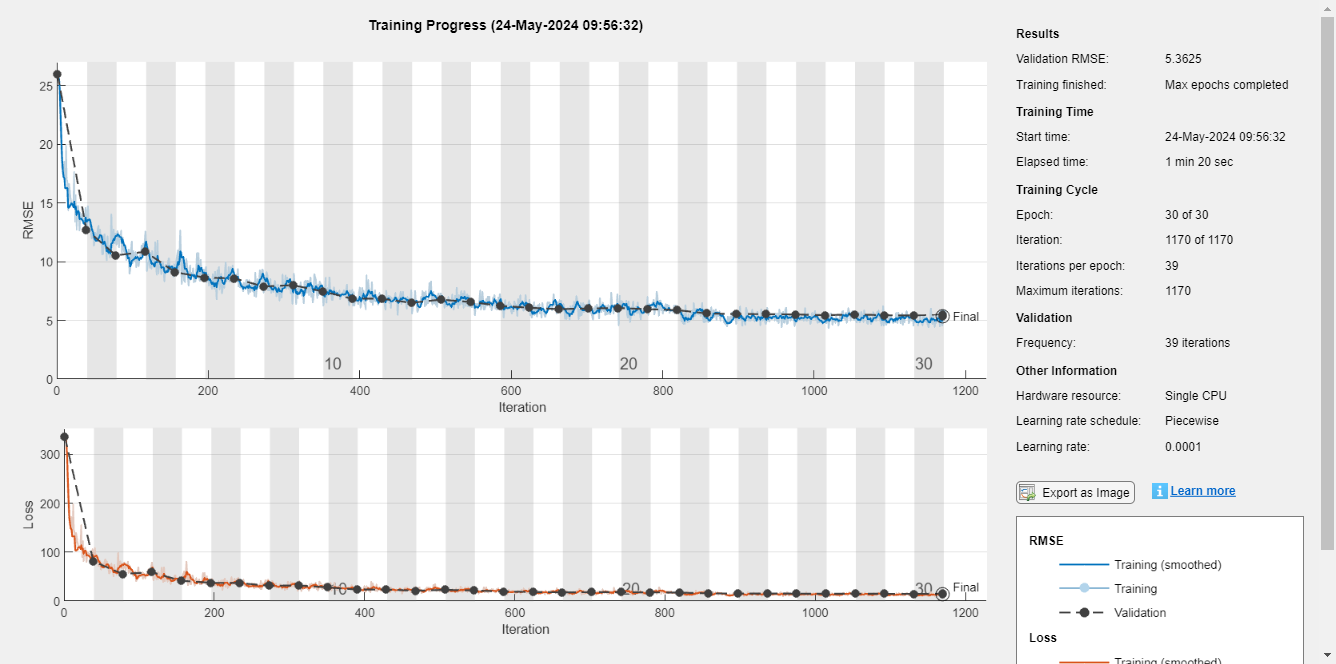

net = trainNetwork(XTrain,YTrain,layers,options);

## 步骤5：测试与评估

YPredicted = predict(net,XValidation);                       % 用训练好的网络预测验证图像中数字倾斜的角度
predictionError = YValidation - YPredicted;                  % 计算预测倾斜角度和实际倾斜角度之间的预测误差
% 计算准确率
thr = 10;                                                    % 设定阈值，在本例中，阈值设定为10度
numCorrect = sum(abs(predictionError) < thr);                % 当预测值与实际值得误差小于10度时，则认为预测正确
numValidationImages = numel(YValidation);                    % 用于验证图像的数量
Accuracy = numCorrect/numValidationImages                    % 计算准确率

Accuracy = 0.9412

% 计算RMSE的值
squares = predictionError.^2;
RMSE = sqrt(mean(squares))

RMSE = single
5.3625

% original layers

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer

    % convolution2dLayer(3,64,'Padding','same')
    % batchNormalizationLayer
    % reluLayer

    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer ];

## Exercise-1

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        27.91 |        25.52 |     389.5237 |     325.5949 |          0.0010 |
|       1 |          39 |       00:00:04 |        14.46 |        12.75 |     104.5097 |      81.2544 |          0.0010 |
|       2 |          50 |       00:00:05 |        11.12 |              |      61.8182 |              |          0.0010 |
|       2 |          78 |       00:00:07 |        11.53 |        10.71 |      66.4905 |   

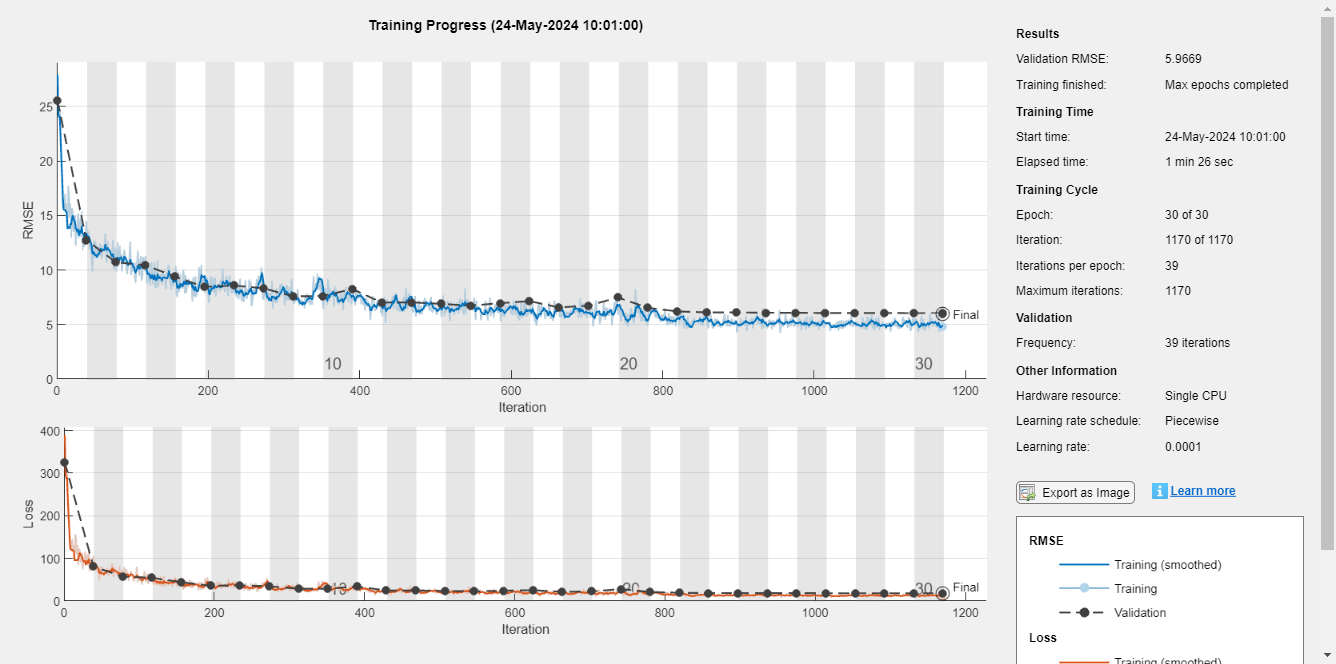

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer

    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer ];

net = trainNetwork(XTrain,YTrain,layers,options);


YPredicted = predict(net,XValidation);
predictionError = YValidation - YPredicted;

% Accuracy
thr = 10;
numCorrect = sum(abs(predictionError) < thr);
numValidationImages = numel(YValidation);
Accuracy = numCorrect/numValidationImages

Accuracy = 0.9134


% RMSE
squares = predictionError.^2;
RMSE = sqrt(mean(squares))

RMSE = single
5.9669

## Exercise-2-1

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        26.26 |        25.60 |     344.7772 |     327.5879 |          0.0010 |
|       1 |          39 |       00:00:04 |        11.61 |        11.56 |      67.4399 |      66.8226 |          0.0010 |
|       2 |          50 |       00:00:05 |        11.15 |              |      62.2051 |              |          0.0010 |
|       2 |          78 |       00:00:07 |        10.66 |        10.87 |      56.8090 |   

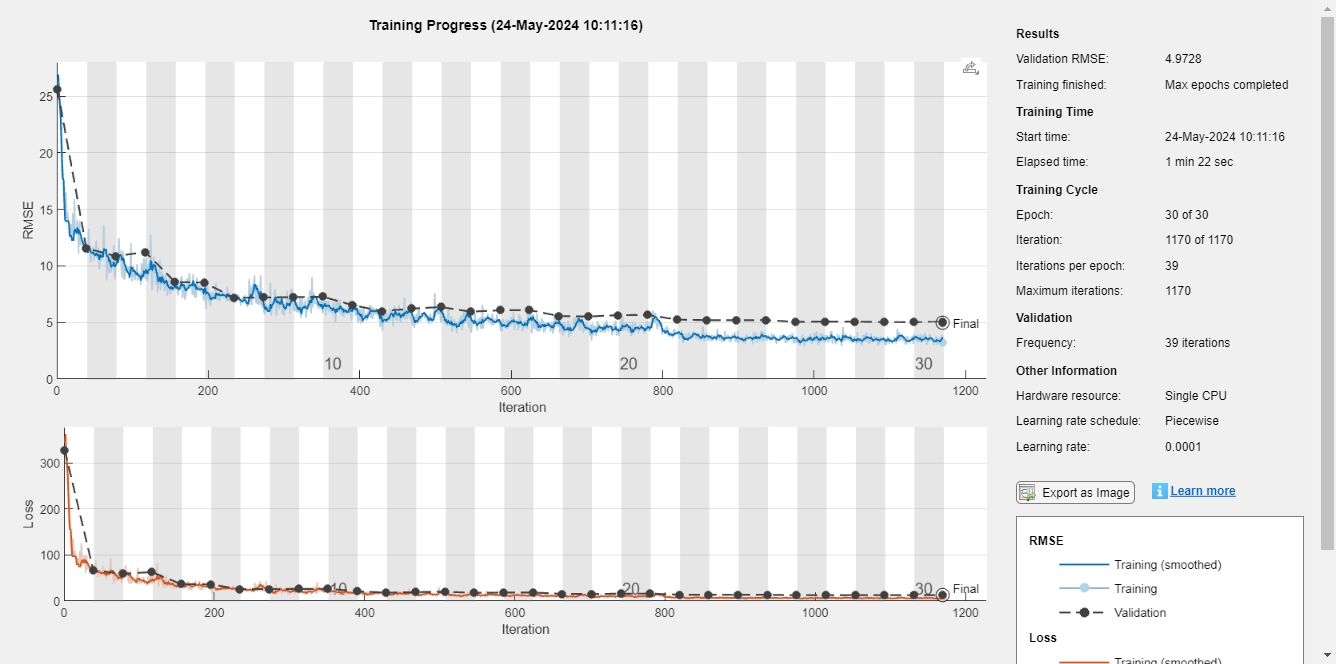

% original layers

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer

    fullyConnectedLayer(1)
    regressionLayer ];

net = trainNetwork(XTrain,YTrain,layers,options);


YPredicted = predict(net,XValidation);
predictionError = YValidation - YPredicted;

% Accuracy
thr = 10;
numCorrect = sum(abs(predictionError) < thr);
numValidationImages = numel(YValidation);
Accuracy = numCorrect/numValidationImages

Accuracy = 0.9554


% RMSE
squares = predictionError.^2;
RMSE = sqrt(mean(squares))

RMSE = single
4.9728

## Exercise-2-2

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        26.03 |        25.99 |     338.8383 |     337.8305 |          0.0010 |
|       1 |          39 |       00:00:05 |        15.34 |        14.52 |     117.6599 |     105.4386 |          0.0010 |
|       2 |          50 |       00:00:06 |        13.82 |              |      95.5306 |              |          0.0010 |
|       2 |          78 |       00:00:08 |        13.33 |        13.04 |      88.7901 |   

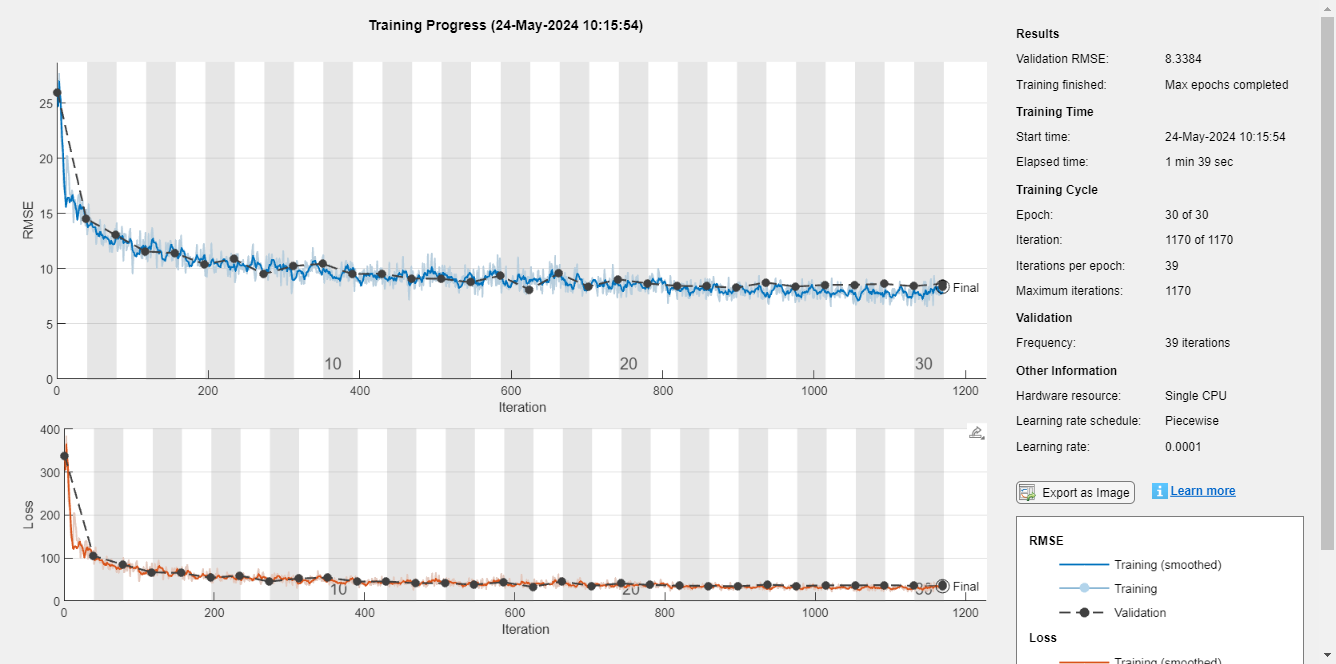

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer(3,8,'Padding','same')
    dropoutLayer(0.2)
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,16,'Padding','same')
    dropoutLayer(0.2)
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding','same')
    dropoutLayer(0.2)
    batchNormalizationLayer
    reluLayer

    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer ];

net = trainNetwork(XTrain,YTrain,layers,options);


YPredicted = predict(net,XValidation);
predictionError = YValidation - YPredicted;

% Accuracy
thr = 10;
numCorrect = sum(abs(predictionError) < thr);
numValidationImages = numel(YValidation);
Accuracy = numCorrect/numValidationImages

Accuracy = 0.7804


% RMSE
squares = predictionError.^2;
RMSE = sqrt(mean(squares))

RMSE = single
8.3384

## Exercise-3

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        26.87 |        25.72 |     361.0811 |     330.6974 |          0.0010 |
|       1 |          39 |       00:00:05 |        13.15 |        12.40 |      86.4637 |      76.8540 |          0.0010 |
|       2 |          50 |       00:00:06 |        13.83 |              |      95.6960 |              |          0.0010 |
|       2 |          78 |       00:00:08 |        12.37 |        11.59 |      76.4768 |   

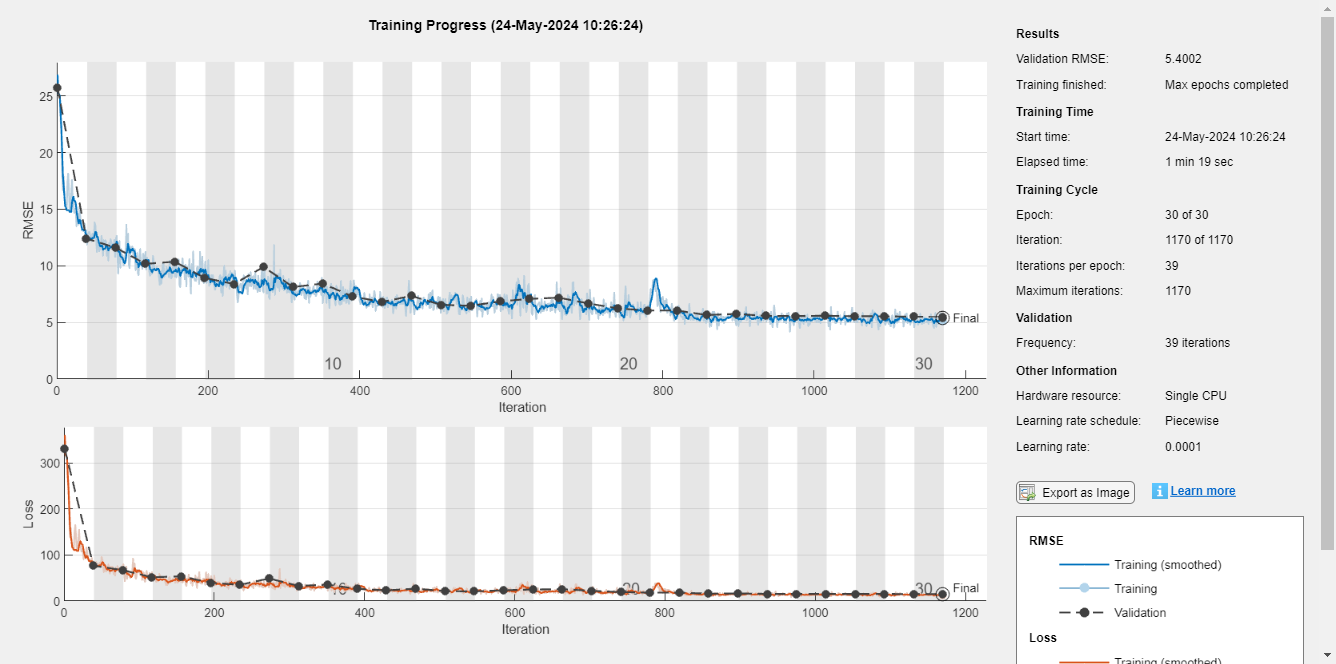

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer

    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer ];

net = trainNetwork(XTrain,YTrain,layers,options);


YPredicted = predict(net,XValidation);
predictionError = YValidation - YPredicted;

% Accuracy
thr = 10;
numCorrect = sum(abs(predictionError) < thr);
numValidationImages = numel(YValidation);
Accuracy = numCorrect/numValidationImages

Accuracy = 0.9408


% RMSE
squares = predictionError.^2;
RMSE = sqrt(mean(squares))

RMSE = single
5.4002

clf('reset')

% test with real image

I = imread('./images/hand_write_5.png');
I45 = imrotate(I, 45, 'crop');
I45 = rgb2gray(I45)

I45 = 28×28 uint8 matrix
     0     0     0     0     0     0     0     0     0     2     0     7     1     1     1     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     3     0     2     0     0     0     0     2     1     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     2     5     3     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     2     3     3     2     0     0     0     0     0     0     3     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     1     1     0     1     0     1     1     0     2     2     2     0     0     0     0     0     0     0    

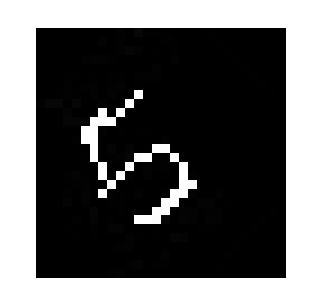

imshow(I45);
truesize([200 200])

predict(net, double(I45)/255)

ans = single
-19.2021

# AlexNet with transfer learning

## Exercise-4

## 步骤1：加载图像数据，并将其划分为训练集和验证集

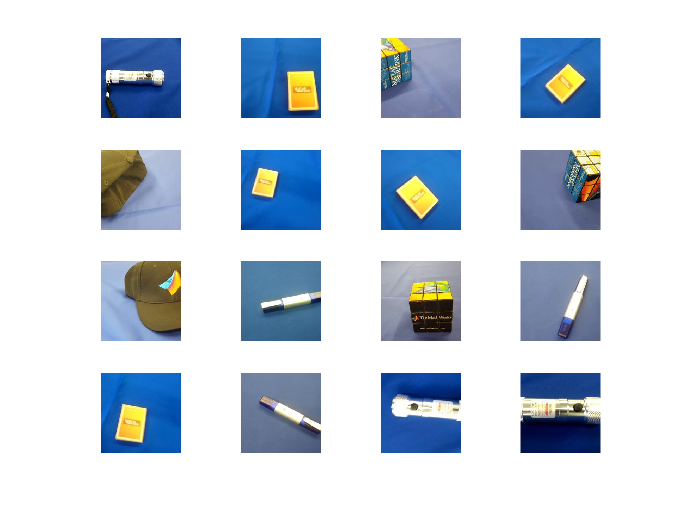

% 加载图像数据
unzip('./data/MerchData.zip');
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

% 划分验证集和训练集
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

% 随机显示训练集中的部分图像
numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

## 步骤2：加载预训练好的网络

% 加载alexnet网络（注：该网络需要提前下载，当输入下面命令时按要求下载即可）
net = alexnet;

## 步骤3：对网络结构进行改进

% 保留AlexNet倒数第三层之前的网络
layersTransfer = net.Layers(1:end-3);

% 确定训练数据中需要分类的种类
numClasses = numel(categories(imdsTrain.Labels));

% 构建新的网络，保留AlexNet倒数第三层之前的网络，在此之后重新添加了全连接
layers = [
    layersTransfer                                       % 保留AlexNet倒数第三层之前的网络
    fullyConnectedLayer(numClasses)                      % 将新的全连接层的输出设置为训练数据中的种类
    softmaxLayer                                         % 添加新的Softmax层
    classificationLayer ];                               % 添加新的分类层

## 步骤4：调整数据集

% 查看网络输入层的大小和通道数
inputSize = net.Layers(1).InputSize;

% 将训练图像的大小调整为与输入层的大小相同
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);

% 将验证图像的大小调整为与输入层的大小相同
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

## 对网络进行训练

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       20.00% |       40.00% |       2.8960 |       1.9698 |      5.0000e-05 |
|       1 |           3 |       00:00:06 |       40.00% |       40.00% |       2.6730 |       1.7133 |      5.0000e-05 |
|       2 |           6 |       00:00:09 |       26.67% |       55.00% |       2.5593 |       1.1835 |      5.0000e-05 |
|       3 |           9 |       00:00:13 |       53.33% |       70.00% |       1.8450 |   

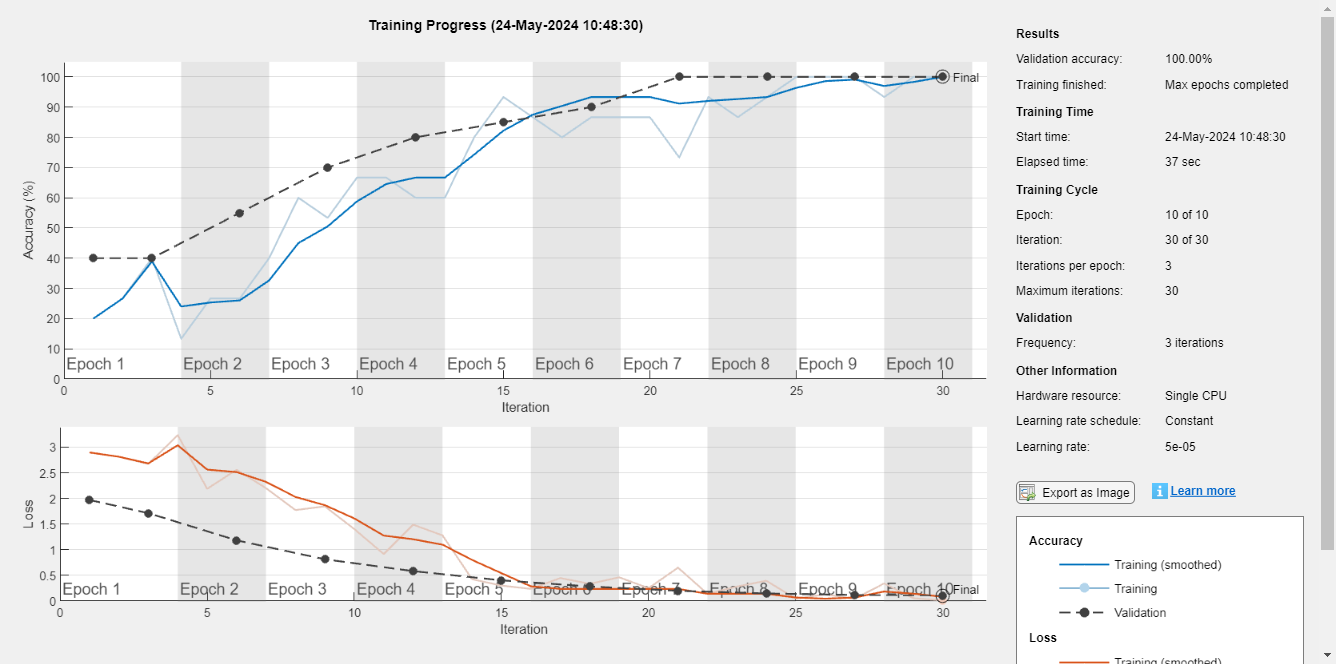

% 对训练参数进行设置
options = trainingOptions('sgdm', ...
    'MiniBatchSize',15, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',0.00005, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',true, ...
    'Plots','training-progress');

% 用训练图像对网络进行训练
netTransfer = trainNetwork(augimdsTrain,layers,options);

## 分类验证图像并并随机显示分类结果

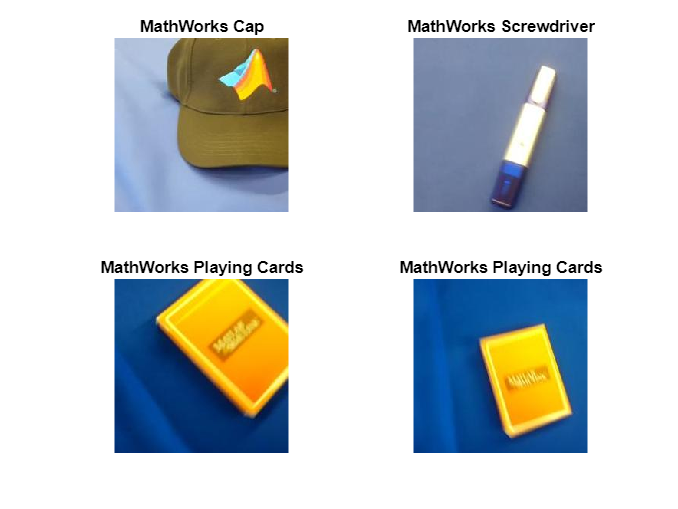

% 对训练好的网络采用验证数据集进行验证
[YPred,scores] = classify(netTransfer,augimdsValidation);

% 随机显示验证效果
idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end

## 计算分类准确率

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 1

## 创建并显示混淆矩阵

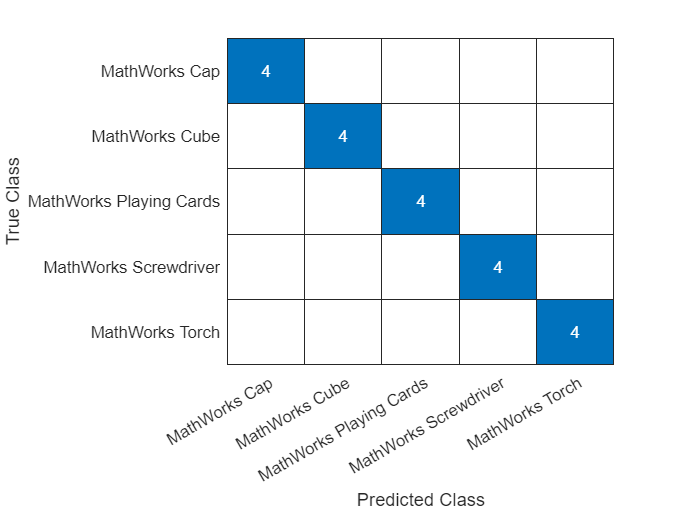

figure
confusionchart(YValidation,YPred)

## Exercise-5

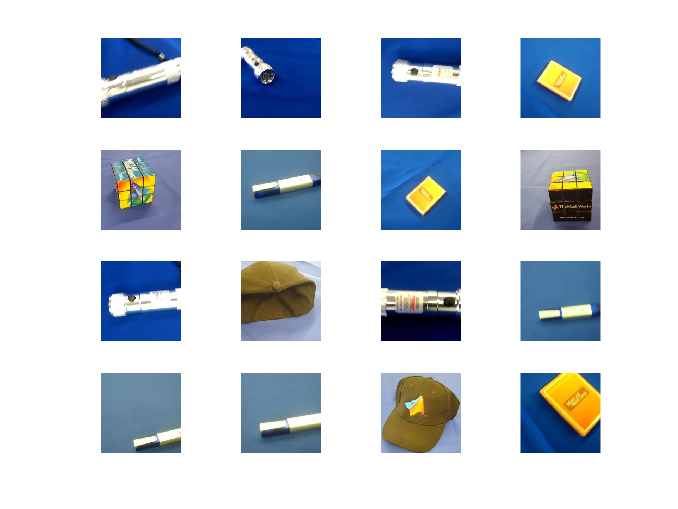

% 加载图像数据
unzip('./data/MerchData.zip', './IMDS/MerchData');
imds = imageDatastore('IMDS/MerchData', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

% 划分验证集和训练集
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

% 随机显示训练集中的部分图像
numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

net = vgg16;
% analyzeNetwork(net)

layersTransfer = net.Layers(1:end-3);

numClasses = numel(categories(imdsTrain.Labels));

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ];

% 查看网络输入层的大小和通道数
inputSize = net.Layers(1).InputSize;

% 将训练图像的大小调整为与输入层的大小相同
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);

% 将验证图像的大小调整为与输入层的大小相同
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:15 |       13.33% |       30.00% |       4.2538 |       2.2510 |      5.0000e-05 |
|       1 |           3 |       00:00:40 |       13.33% |       40.00% |       3.6386 |       1.6201 |      5.0000e-05 |
|       2 |           6 |       00:01:12 |       60.00% |       75.00% |       1.1786 |       0.7998 |      5.0000e-05 |
|       3 |           9 |       00:01:44 |       60.00% |       90.00% |       0.8684 |   

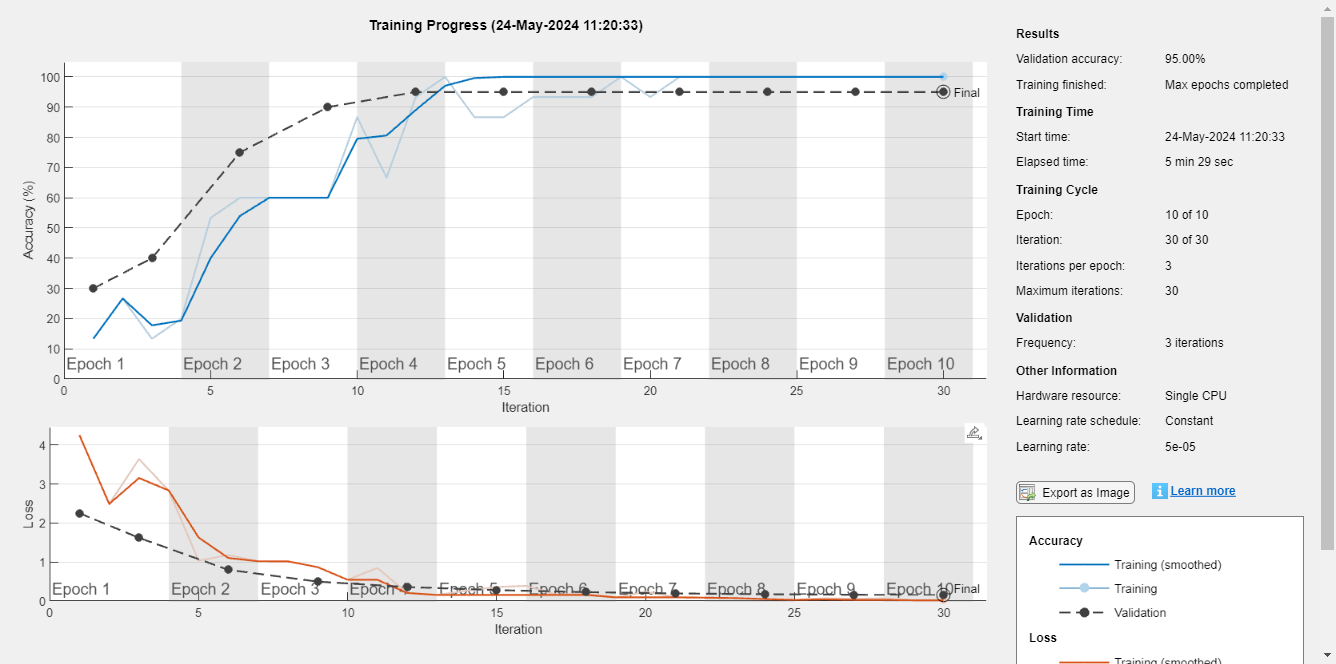

% 对训练参数进行设置
options = trainingOptions('sgdm', ...
    'MiniBatchSize',15, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',0.00005, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',true, ...
    'Plots','training-progress');

% 用训练图像对网络进行训练
netTransfer = trainNetwork(augimdsTrain,layers,options);

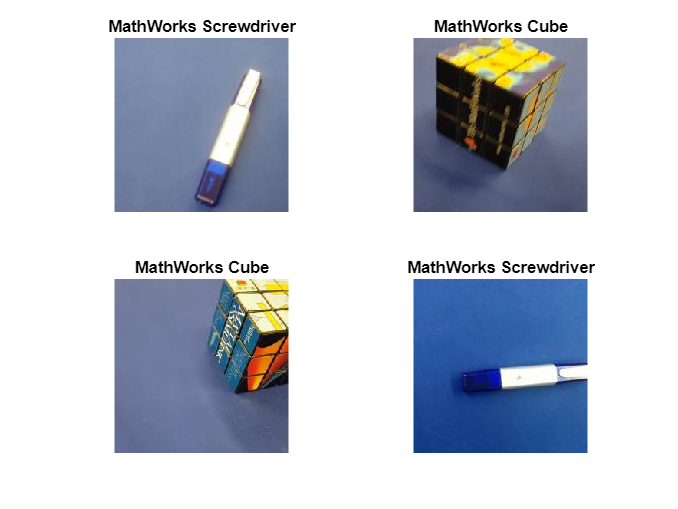

% 对训练好的网络采用验证数据集进行验证
[YPred,scores] = classify(netTransfer,augimdsValidation);

% 随机显示验证效果
idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.9500

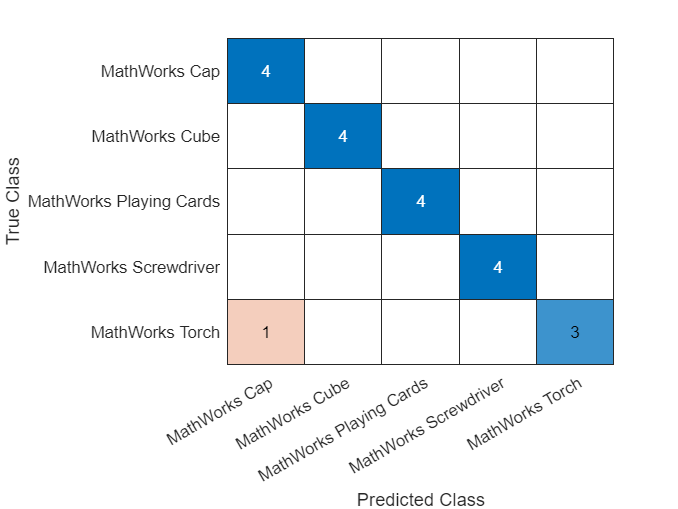

figure
confusionchart(YValidation,YPred)

## Exercise-6

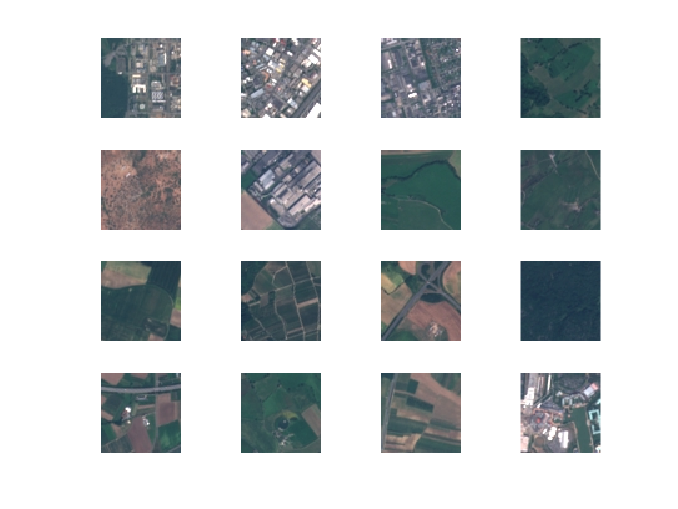

% 加载图像数据
unzip('./data/small_EUROSat.zip', './IMDS/small_EUROSat');
imds = imageDatastore('IMDS/small_EUROSat', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

% 划分验证集和训练集
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

% 随机显示训练集中的部分图像
numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

net = alexnet;

layersTransfer = net.Layers(1:end-3);

numClasses = numel(categories(imdsTrain.Labels));

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ];

% 查看网络输入层的大小和通道数
inputSize = net.Layers(1).InputSize;

% 将训练图像的大小调整为与输入层的大小相同
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);

% 将验证图像的大小调整为与输入层的大小相同
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       26.67% |       16.19% |       2.7319 |       2.6052 |      5.0000e-05 |
|       1 |           3 |       00:00:10 |       33.33% |       15.24% |       3.1596 |       2.4217 |      5.0000e-05 |
|       1 |           6 |       00:00:17 |       40.00% |       20.48% |       2.3993 |       2.0914 |      5.0000e-05 |
|       1 |           9 |       00:00:23 |       13.33% |       21.90% |       2.9472 |   

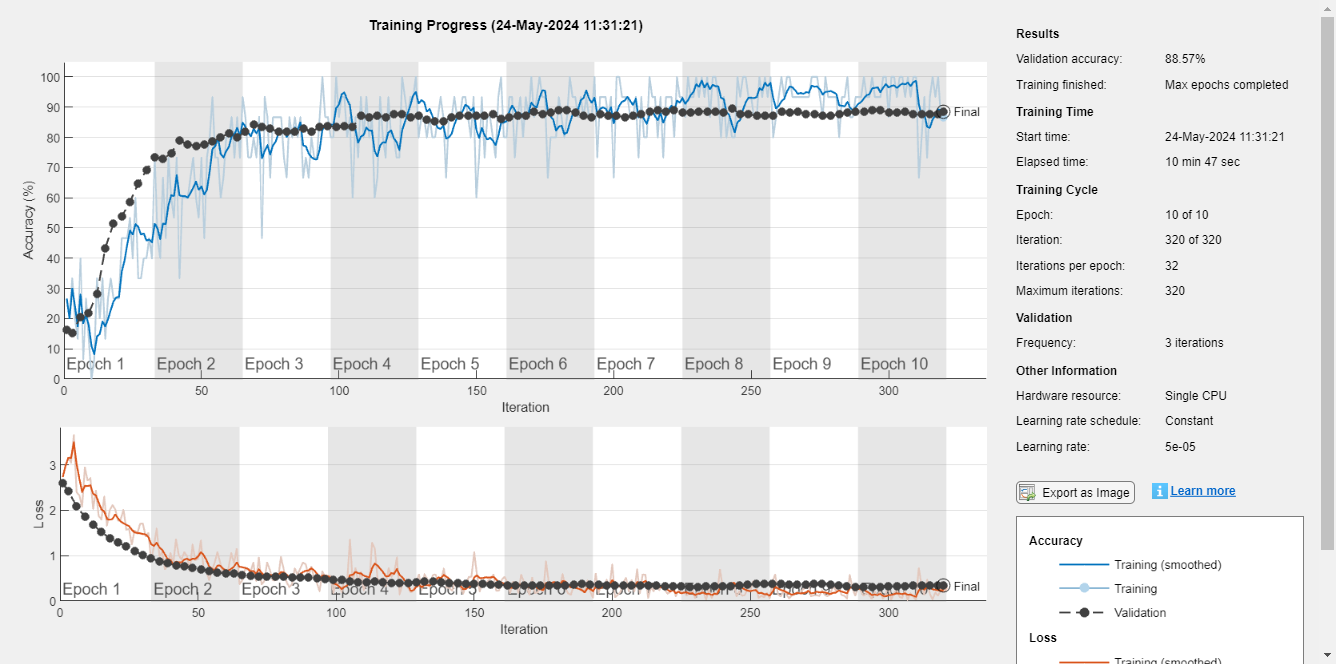

% 对训练参数进行设置
options = trainingOptions('sgdm', ...
    'MiniBatchSize',15, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',0.00005, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',true, ...
    'Plots','training-progress');

% 用训练图像对网络进行训练
netTransfer = trainNetwork(augimdsTrain,layers,options);

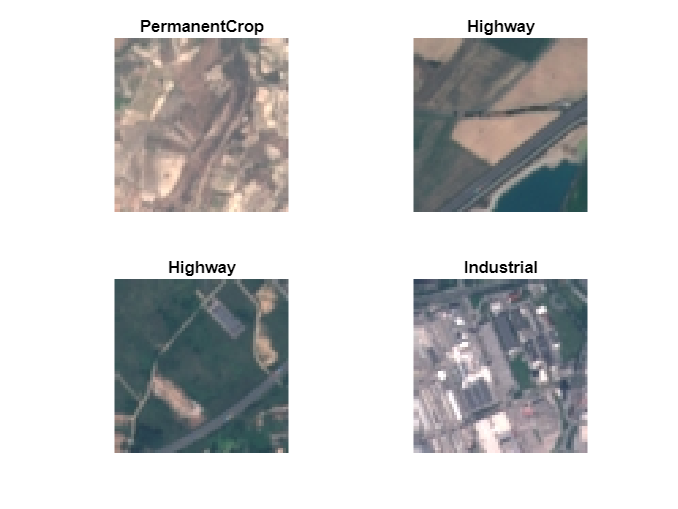

% 对训练好的网络采用验证数据集进行验证
[YPred,scores] = classify(netTransfer,augimdsValidation);

% 随机显示验证效果
idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.8857

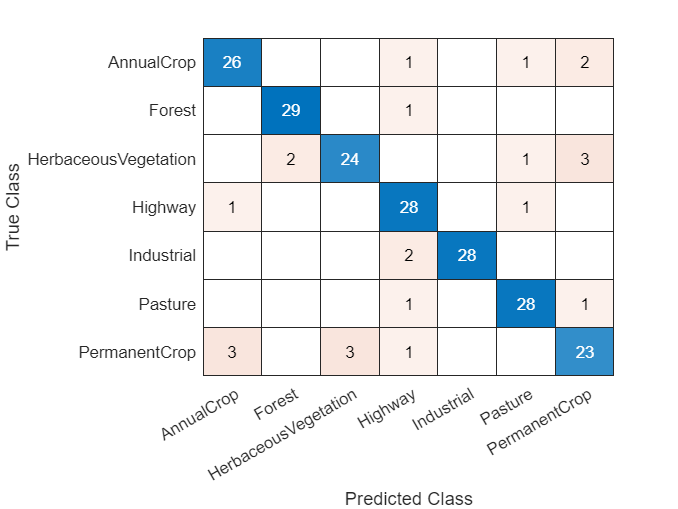

figure
confusionchart(YValidation,YPred)